# Elliptic Equation - Laplace (Finite Difference approach)

Consider the following pde - it represents the partial differential equation for a 2D **Steady State** heat conduction problem

- 
$$\frac{\partial^{\;2} T}{\partial x^2 }\;\;+\;\;\frac{\partial^{\;2} T}{\partial y^2 }\;\;=\;\;0$$


With the domain and Boundary conditions shown below:

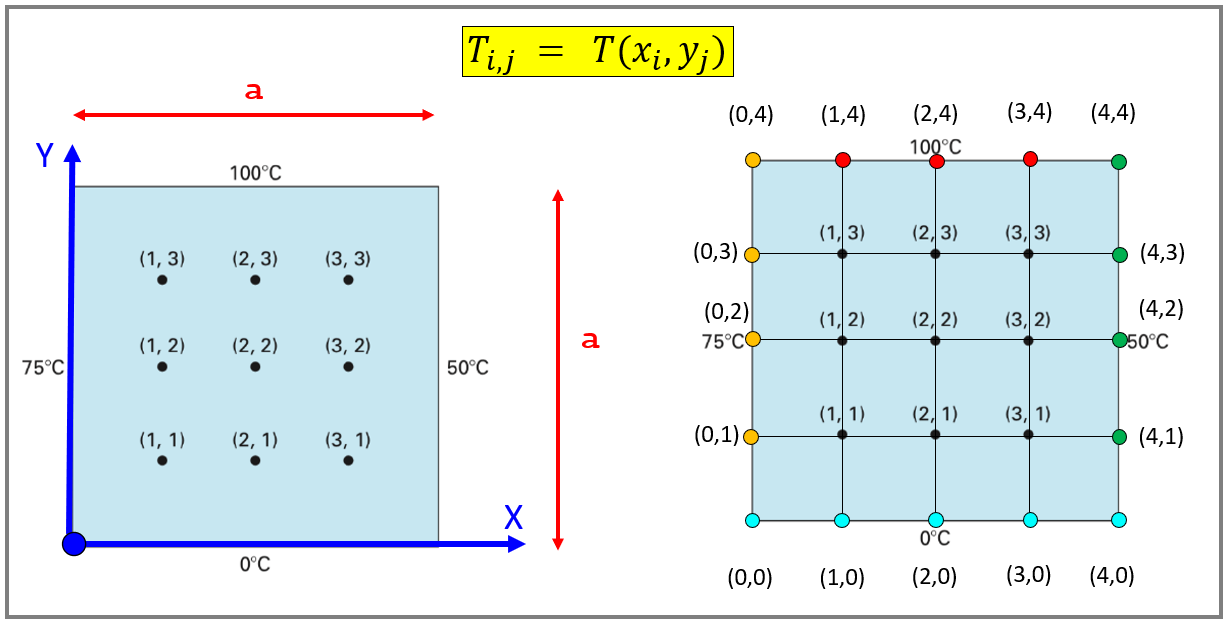

**History:**

- `Apr-2021 : Created(bhorton@mathworks.com)`

## Prework:

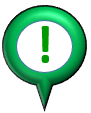 **ATTENTION: ** Before starting this tutorial, have a look at the short(VERY !) script called [`bh_pre_work_table_essentials.mlx`](matlab:  edit bh_pre_work_table_essentials.mlx) - it introduces a data container called a **table**. The **table** data type is SUPER convenient for assembling the system matrices that we'll encounter in THIS case study !

## The design task:

clc 
clear

**Define the Grid size**

n    = 50; % NUM intervals
a    = 10;                   % dimension of the plate
h    = a/n;                  % SPATIAL step

Npt  = n + 1;               % number of points in each of x, y directions
Ndof = Npt*Npt;             % total number of GRID points

**Define the Boundary Conditions**

T0_BC_BOTTOM =   0; % boundary conditions in oC
T1_BC_LEFT   =  75;
T2_BC_RIGHT  =  50;
T3_BC_TOP    = 100;

BC_T_MIN     = min([T0_BC_BOTTOM, T1_BC_LEFT, T2_BC_RIGHT, T3_BC_TOP]);
BC_T_MAX     = max([T0_BC_BOTTOM, T1_BC_LEFT, T2_BC_RIGHT, T3_BC_TOP]);

**Define the grid points**

x  = linspace(0, a, Npt); % to generate equally spaced (n + 1) points in x
y  = linspace(0, a, Npt); % to generate equally spaced (n + 1) points in y

### Our Problem formulation:

Consider then the simple grid shown below - it is for the case where we have **4** intervals

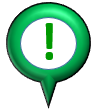 **ATTENTION: ** ****** STENCIL DERIVATION ******

- The Derivation for our Finite Difference Stencil is in the file [`bh_deriv_for_2d_pde_ellip_heat_ss.mlx`](matlab:  edit bh_deriv_for_2d_pde_ellip_heat_ss.mlx)

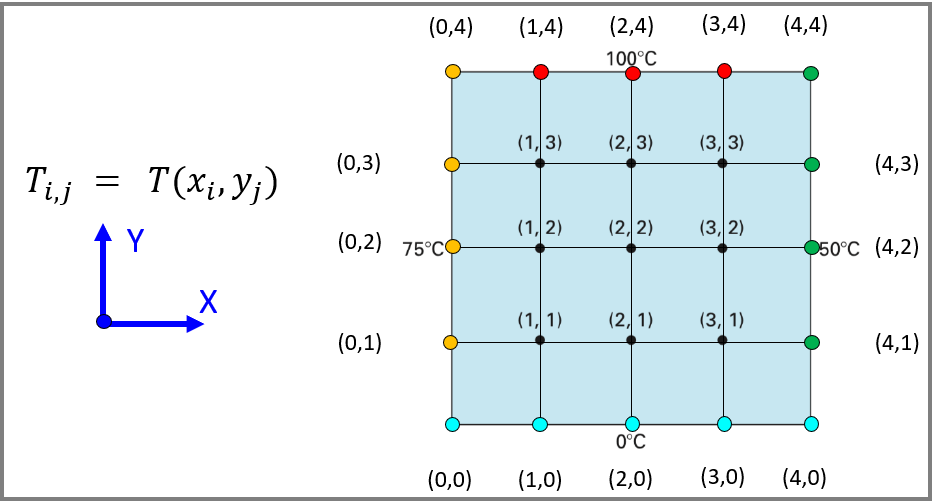

For this simple grid, we have a series of grid points .... which we'll call **NODES**.  For each NODE, observe the following:

- A NODE has an ID - say $i,j$

- A NODE has co-ordinates $\left(x_i \;\;\;,\;y_j \right)$

- A NODE has a Temperature  $T_{i\;\;,\;j}$

- Some NODES are BOUNDARY condition nodes - we already know the temperatures at these nodes !

- Some NODES are INTERNAL nodes - so we can write out the Finite Difference stencil for these nodes

For the simple grid shown above we have 25 NODES. For each NODE we can either:

-  write out the Finite Difference stencil      $T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$

- **OR** we can write out the known temperature, because the NODE is at a boundary condition

- NOTE:  the **derivation** of the stencil equation is in [`bh_deriv_for_2d_pde_ellip_heat_ss.mlx`](matlab:  edit bh_deriv_for_2d_pde_ellip_heat_ss.mlx)

We can then collect/organise these equations in MATRIX form.  The MATRIX form of our system will have the shape: 

-   
$$A\;\ldotp z=\textrm{rhs}$$
 

where:

- 
$$\textrm{transpose}\left(z\right)=\left\lbrack T_{0,0} \;\;T_{1,0} \;\;T_{2,0} \;\;T_{3,0} \;\;T_{4,0} \;\;\;\;\;\;\;T_{0,1} \;\;T_{1,1} \;\;T_{2,1} \;\;T_{3,1} \;\;T_{4,1} \;\;\;\;\;\;T_{0,2} \;\;T_{1,2} \;\;T_{2,2} \;\;T_{3,2} \;\;T_{4,2} \;\;\;\;\;\;\;T_{0,3} \;\;T_{1,3} \;\;T_{2,3} \;\;T_{3,3} \;\;T_{4,3} \;\;\;\;\;\;\;\;T_{0,4} \;\;T_{1,4} \;\;T_{2,4} \;\;T_{3,4} \;\;T_{4,4} \right\rbrack \;$$


Once we have our system MATRICES $A$ and $\textrm{rhs}$, we can then solve for the unknown temperatures via:    $z=A\backslash \textrm{rhs}$

**ATTENTION:**   Here's what the $A$ and $\textrm{rhs}$ matrices look like for the ***specific case*** of the $5\times 5$ grid

### 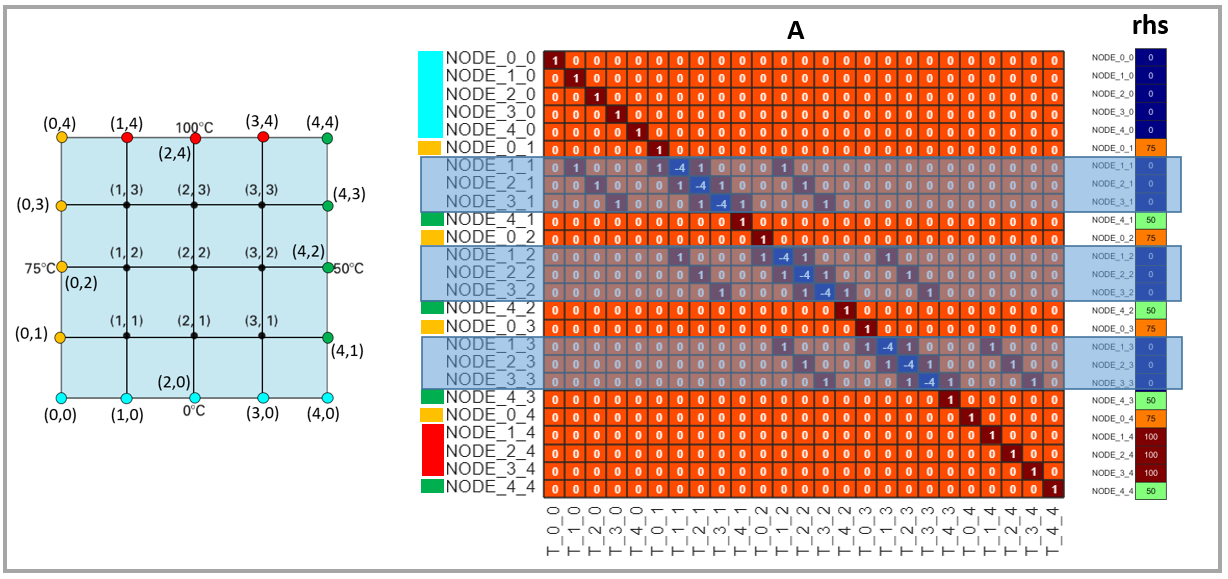

### Create some TABLES

To help with the "book keeping" of assembling our system MATRICES, let's use TABLES.  We'll label our columns and we'll label our rows.

- The ROW labels will take the form:  `NODE_i_j`

- The COLUMN labels will take the form:  `T_i_j`

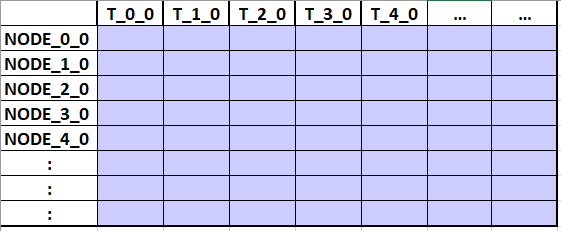

We can then use these meaningful labels to "index" into the table, eg: with TABLES we can do stuff like this:

So first, let's generate the ROW and COLUMN label names:

   T_name_list = strings(   1, Ndof ); % preallocate COLUMN names
NODE_name_list = strings(   1, Ndof ); % preallocate ROW names
NODE_coord_mat =   zeros(Ndof, 4    ); % preallocate a matrix containing the NODE x,y ANd i,j co-ords

count =0;
for jj_ID=0:(Npt-1)
    for ii_ID=0:(Npt-1)
        count = count + 1;
        T_name_list(count)    = "T_"    + ii_ID + "_" + jj_ID;
        NODE_name_list(count) = "NODE_" + ii_ID + "_" + jj_ID;
        
        NODE_coord_mat(count, : ) = [ x(ii_ID+1), y(jj_ID+1), ii_ID, jj_ID ];
    end
end

Our Tables are initially populated with **ZERO** values:

A_TAB   = array2table(zeros(Ndof, Ndof), "RowNames",NODE_name_list, "VariableNames",  T_name_list);
rhs_TAB = array2table(zeros(Ndof,1),     "RowNames",NODE_name_list, "VariableNames", "T");

 So this is what our $A$ table looks like BEFORE we populate it with values.

- **NOTE: ** the ROW and COLUMN labels ... because we'll use these labels to "index" into the table

A_TAB

A_TAB = 2601×2601 table
                 T_0_0    T_1_0    T_2_0    T_3_0    T_4_0    T_5_0    T_6_0    T_7_0    T_8_0    T_9_0    T_10_0    T_11_0    T_12_0    T_13_0    T_14_0    T_15_0    T_16_0    T_17_0    T_18_0    T_19_0    T_20_0    T_21_0    T_22_0    T_23_0    T_24_0    T_25_0    T_26_0    T_27_0    T_28_0    T_29_0    T_30_0    T_31_0    T_32_0    T_33_0    T_34_0    T_35_0 

OK: Let's process each NODE in our grid and recall that an "internal" node has an equation of the form:

-   
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$$


for kk=1:length(NODE_name_list)
    % what NODE are we processing
    NODE_ID_str   = NODE_name_list(kk);

    % what is the (i,j) ID for this node
    ii_ID         = NODE_coord_mat(kk,3);
    jj_ID         = NODE_coord_mat(kk,4);    

    T_ID_str      =    "T_"  + ii_ID  + "_" + jj_ID;
              
    % CLASSIFY the node
    if(          0==jj_ID),   NODE_TYPE = "BC_BOTTOM";
    elseif(      0==ii_ID),   NODE_TYPE = "BC_LEFT";
    elseif((Npt-1)==ii_ID),   NODE_TYPE = "BC_RIGHT";
    elseif((Npt-1)==jj_ID),   NODE_TYPE = "BC_TOP";
    else,                     NODE_TYPE = "INTERNAL"; 
    end
    
    % PROCESS the node
    switch(NODE_TYPE)  
        case "INTERNAL"    
             A_TAB{NODE_ID_str, ("T_" + (ii_ID+1) + "_" +  jj_ID)   } =  1;
             A_TAB{NODE_ID_str, ("T_" + (ii_ID-1) + "_" +  jj_ID)   } =  1; 
             A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" + (jj_ID+1))} =  1;           
             A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" + (jj_ID-1))} =  1;   
             A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" +  jj_ID)   } = -4;                
        case "BC_BOTTOM"
                         A_TAB{ NODE_ID_str,   T_ID_str} = 1;
                       rhs_TAB{ NODE_ID_str,   1       } = T0_BC_BOTTOM;                 
        case "BC_LEFT"
                         A_TAB{ NODE_ID_str,   T_ID_str} = 1;
                       rhs_TAB{ NODE_ID_str,   1       } = T1_BC_LEFT;                  
        case "BC_RIGHT"
                         A_TAB{ NODE_ID_str,   T_ID_str} = 1;
                       rhs_TAB{ NODE_ID_str,   1       } = T2_BC_RIGHT;                 
        case "BC_TOP"
                         A_TAB{ NODE_ID_str,   T_ID_str} = 1;
                       rhs_TAB{ NODE_ID_str,   1       } = T3_BC_TOP;                                                                                             
        otherwise
            error("###_ERROR:  Bad !")
    end % switch
        
end     % for kk

## Inspect our system A and b tables

 Let's have a look at our assembled system TABLES.

- *NOTE:   for *`n>10 `*... it's just too messy to read the ROW and COLUMN labels in the HEATMAP*

if(n<=10)
    % the heatmap() function will apply LaTex interpretation to the ROW,COL strings
    no_subs_NODE_name_list = replace(NODE_name_list, "_", "\_");
    no_subs_T_name_list    = replace(T_name_list   , "_", "\_");
    
    figure;
        h1 = heatmap(no_subs_T_name_list, no_subs_NODE_name_list, A_TAB{:,:} ); colormap(jet)
                title("The A table")
    
    figure;
        h2 = heatmap("my_RHS", no_subs_NODE_name_list, rhs_TAB{:,:} ); colormap(jet)
                title("The rhs table")  
end

Echo the table too:

A_TAB 

A_TAB = 2601×2601 table
                 T_0_0    T_1_0    T_2_0    T_3_0    T_4_0    T_5_0    T_6_0    T_7_0    T_8_0    T_9_0    T_10_0    T_11_0    T_12_0    T_13_0    T_14_0    T_15_0    T_16_0    T_17_0    T_18_0    T_19_0    T_20_0    T_21_0    T_22_0    T_23_0    T_24_0    T_25_0    T_26_0    T_27_0    T_28_0    T_29_0    T_30_0    T_31_0    T_32_0    T_33_0    T_34_0    T_35_0 

## Compute the solution

To compute the solution, let's pull the data out of the TABLES and assign it to "regular" MATRICES

A   =   A_TAB{:,:};
rhs = rhs_TAB{:,1};

whos A rhs

  Name         Size                 Bytes  Class     Attributes

  A         2601x2601            54121608  double              
  rhs       2601x1                  20808  double              



Now solve the system of linear equations   $A\ldotp T_{\textrm{RESULTS}} =\textrm{rhs}$      

 T_results =  A \ rhs

T_results =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


** REMEMBER: **that the `T_results` array contains the values:

- 
$$\left\lbrack T_{0,0} \;\;T_{1,0} \;\;T_{2,0} \;\;T_{3,0} \;\;T_{4,0} \cdots \;\;\;\;\;\;\;T_{0,1} \;\;T_{1,1} \;\;T_{2,1} \;\;T_{3,1} \;\;T_{4,1} \cdots \;\;\;\;\;\;T_{0,2} \;\;T_{1,2} \;\;T_{2,2} \;\;T_{3,2} \;\;T_{4,2} \cdots \;\;\;\;\;\;\;T_{0,3} \;\;T_{1,3} \;\;T_{2,3} \;\;T_{3,3} \;\;T_{4,3} \cdots \;\;\;\;\;\;\;\;T_{0,4} \;\;T_{1,4} \;\;T_{2,4} \;\;T_{3,4} \;\;T_{4,4} \cdots \right\rbrack$$


- where:   $T_{i\;\;,\;j} \;=T\left(x_i \;,y_j \right)$

## Visualize the solution - Part 1

Let's first plot the results as a 3D scatter plot:

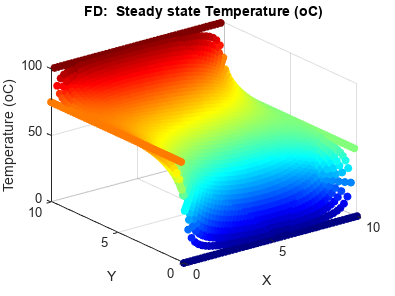

the_x_list = NODE_coord_mat(:,1);
the_y_list = NODE_coord_mat(:,2);
the_T_list = T_results;

figure;
    scatter3(the_x_list, the_y_list, the_T_list, [],the_T_list, 'filled')
        xlabel("X");  ylabel("Y");  zlabel("Temperature (oC)")
        title('FD:  Steady state Temperature (oC)')
        colormap(jet)

If you only have a small number of points in your grid .... it can be difficult to "see" the surface of the temperature distribution. We'll look at another/better visualization next

## Visualize the solution - Part 2

First recall the size

whos  T_results       

  Name              Size            Bytes  Class     Attributes

  T_results      2601x1             20808  double              



 and values of some relevant variables:

Npt

Npt = 51

Let's view our data as a SURFACE.  To do this we need to "shape" our Temperature data array `T_results`, into a MATRIX that is arranged as shown below: (see the DOC on the [`surf()`](matlab:  doc surf) and [`meshgrid()`](matlab: doc meshgrid) functions.)

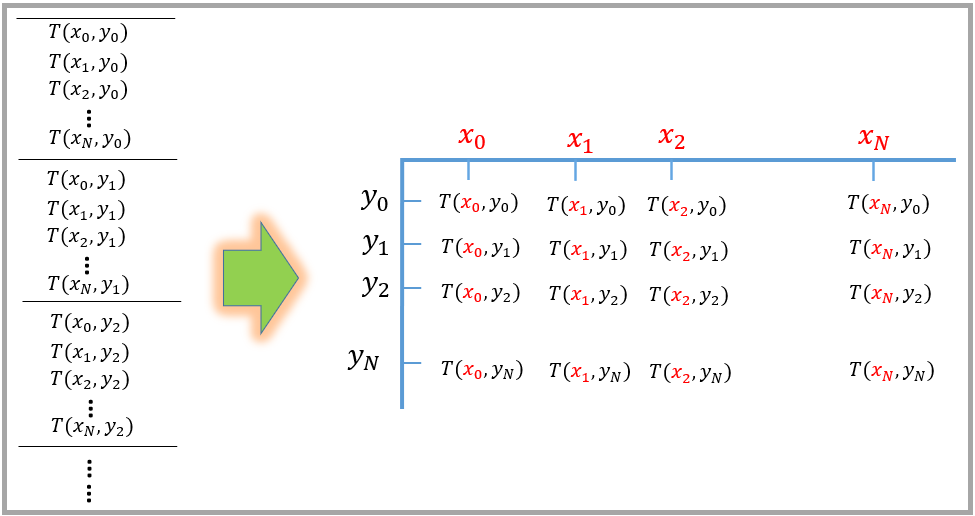

[the_x_mat, the_y_mat] = meshgrid(x, y);

the_T_mat = zeros(size(the_x_mat));
for kk=1:Npt
    the_inds = (kk-1)*Npt  +  (1:Npt);
    
    the_T_mat(kk, :) = T_results(the_inds);
end

Now we can plot the surface

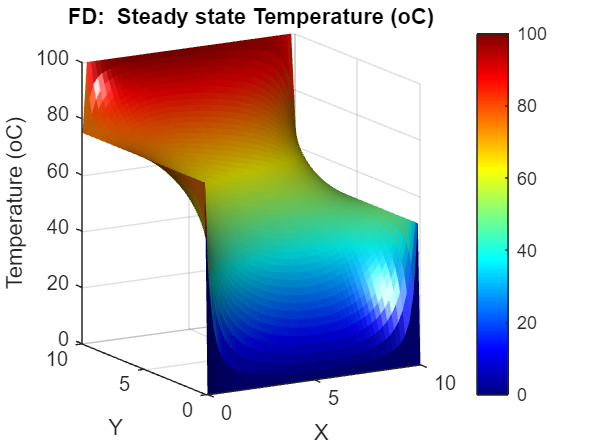

figure;
    surf(the_x_mat, the_y_mat, the_T_mat, "EdgeColor","none")
        set(gca,"CLim", [BC_T_MIN, BC_T_MAX])
        xlabel("X");  ylabel("Y");  zlabel("Temperature (oC)")
        colorbar
        camlight('headlight')
        colormap(jet)
        title('FD:  Steady state Temperature (oC)')
    if(Npt<=11)
      hold("on");
      scatter3(the_x_list,the_y_list,the_T_list,[],'r', 'filled')
    end
    view([-30.4 11.8])

## Visualize the solution - Part 3

Let's view our data as a CONTOUR plot - see DOC [`contour`](matlab: doc contour) and [`contour3`](matlab: doc contour3)

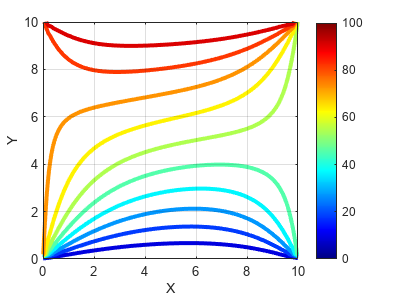

figure;
    NUM_C_LEVELS = 10;
    [~, c_props] = contour(the_x_mat, the_y_mat, the_T_mat,  NUM_C_LEVELS);
        c_props.LineWidth = 3;
        xlabel("X");  ylabel("Y");  zlabel("Temperature (oC)"); grid("on");
        set(gca,"CLim", [BC_T_MIN, BC_T_MAX])
        colorbar
        colormap(jet)

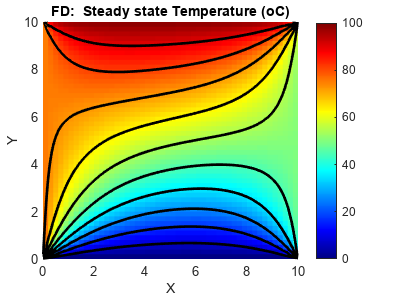


figure;
    surf(the_x_mat, the_y_mat, the_T_mat, "EdgeColor","none"); %, "FaceAlpha",0.7);
       hold("on")
    [~, c_props] = contour3(the_x_mat, the_y_mat, the_T_mat, NUM_C_LEVELS,'-k');
        c_props.LineWidth = 2;
        xlabel("X");  ylabel("Y");  zlabel("Temperature (oC)"); 
        set(gca,"CLim", [BC_T_MIN, BC_T_MAX])
        colorbar
        colormap(jet)
        view(2)
        title('FD:  Steady state Temperature (oC)')

# **Extra credit:**  solve using the PDE toolbox

We can solve this same problem using the [**PDE Toolbox**](matlab:  web(fullfile(docroot, 'pde/index.html'))) to solve a 2D Thermal Analysis problem.

## Create a Thermal Steady state model

thermalmodel = createpde('thermal','steadystate');          

## Define the geometry

Define the geometry of our system (it's just a square of side length $a$) using the  [`decsg`](matlab:  doc decsg) function

gdm_COL      = [3 4   0   a   a   0 ...
                      0   0   a   a   ]';
ns           = ['R1A']'; 
g            = decsg(gdm_COL,'R1A',ns);

This geometry gets "absorbed" into our thermal model by using the  [`geometryFromEdges`](matlab:  doc geometryFromEdges)() function:

geometryFromEdges(thermalmodel,g);

## Visualize the geometry

We can visualize our square using the [`pdegplot`](matlab:  web(fullfile(docroot, 'pde/ug/pdegplot.html'))) function:

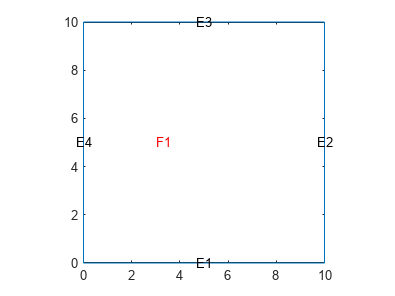

figure;
    pdegplot(thermalmodel,'EdgeLabels','on','SubdomainLabels','on')
        axis equal

## Set the Boundary conditions

Next we need to set the 4 boundary conditions of the square.  To do this we use the EDGE labels displayed by the [`pdegplot`](matlab:  web(fullfile(docroot, 'pde/ug/pdegplot.html')))

thermalBC(thermalmodel,'Edge',1,'Temperature',T0_BC_BOTTOM);   
thermalBC(thermalmodel,'Edge',3,'Temperature',T3_BC_TOP); 
thermalBC(thermalmodel,'Edge',4,'Temperature',T1_BC_LEFT);   
thermalBC(thermalmodel,'Edge',2,'Temperature',T2_BC_RIGHT); 

## Specify Thermal Properties of the Materials

Specify the thermal conductivity of the material.

-      
$$k\;\;\left\lbrack \frac{W}{m\ldotp K}\right\rbrack$$
   

thermalProperties(thermalmodel, 'Face', 1, 'ThermalConductivity',1); 

## Generate the mesh

Now generate the Finite Element mesh using the function [`generateMesh`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.generatemesh.html')))

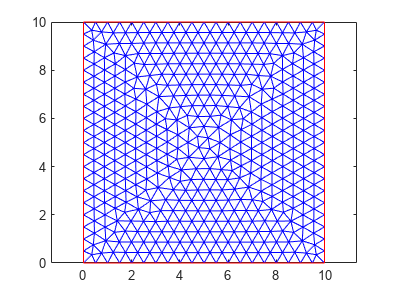

generateMesh(thermalmodel, 'Hmax', a/20);

figure
    pdeplot(thermalmodel)

## Calculate Solution

Use the [`solve`](matlab:  web(fullfile(docroot, 'pde/ug/pde.thermalmodel.solve.html'))) function to calculate the solution.

- NOTE:  the returned result will be a [`SteadyStateThermalResults`](matlab:  web(fullfile(docroot, 'pde/ug/pde.steadystatethermalresults.html'))) object

thermalresults = solve(thermalmodel)

thermalresults =   SteadyStateThermalResults with properties:

    Temperature: [1893×1 double]
     XGradients: [1893×1 double]
     YGradients: [1893×1 double]
     ZGradients: []
           Mesh: [1×1 FEMesh]


## Visualize the solution:

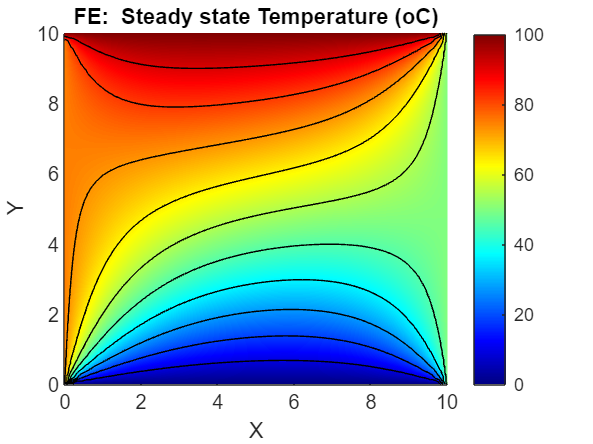

figure;
    pdeplot(thermalmodel,'XYData',thermalresults.Temperature,'ColorMap','jet', "Contour","on", "Levels", 10);
        xlabel('X');
        ylabel('Y');
        title('FE:  Steady state Temperature (oC)')

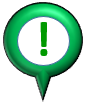**ATTENTION:**  And it's a similar looking response to the one that we computed using our own Finite Difference implementation